clear all
close all
clc

global A
global B
global control
% (J)     moment of inertia of the rotor     
% (b)     motor viscous friction constant   
% (Ke)    electromotive force constant       
% (Kt)    motor torque constant              
% (R)     electric resistance                
% (L)     electric inductance                

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;

A = [0 1 0
    0 -b/J K/J
    0 -K/L -R/L];
B = [0 ; 0 ; 1/L];
C = [1  0  0];
D = 0;

eig(A)

ans = 	1.0e+06 *

         0
   -0.0001
   -1.4545


rank(ctrb(A,B))

ans = 2


sys = ss(A,B,C,[]);
x0 = [0; 0; 0];

% sysd = c2d(sys, 0.02);
% pidTuner(sysd,'pid')

# Timing Parameters

dt = 0.02;
t_total = 10;
t_span = 0:dt:t_total;

% target measurement - pulse
ref_fuc = @(i) 5-mod(floor(i*dt/4),2);
ref = zeros(size(t_span,2),1);
for i = 1:length(ref)
    ref(i,1) = ref_fuc(i);
end

# PID Parameters

global windupGuard;
global proportional_gain;
global integral_gain;
global derivative_gain;
global prev_error;
global int_error;
global control;

% set these as needed
control = 0;
windupGuard = 100;
proportional_gain = 0.2;%0.08041;
integral_gain = 0;%0.02288;
derivative_gain = 0;%0.004505;
 
% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

% call update function
%pid_update(19, 1.0)

# Simulation - No attacks

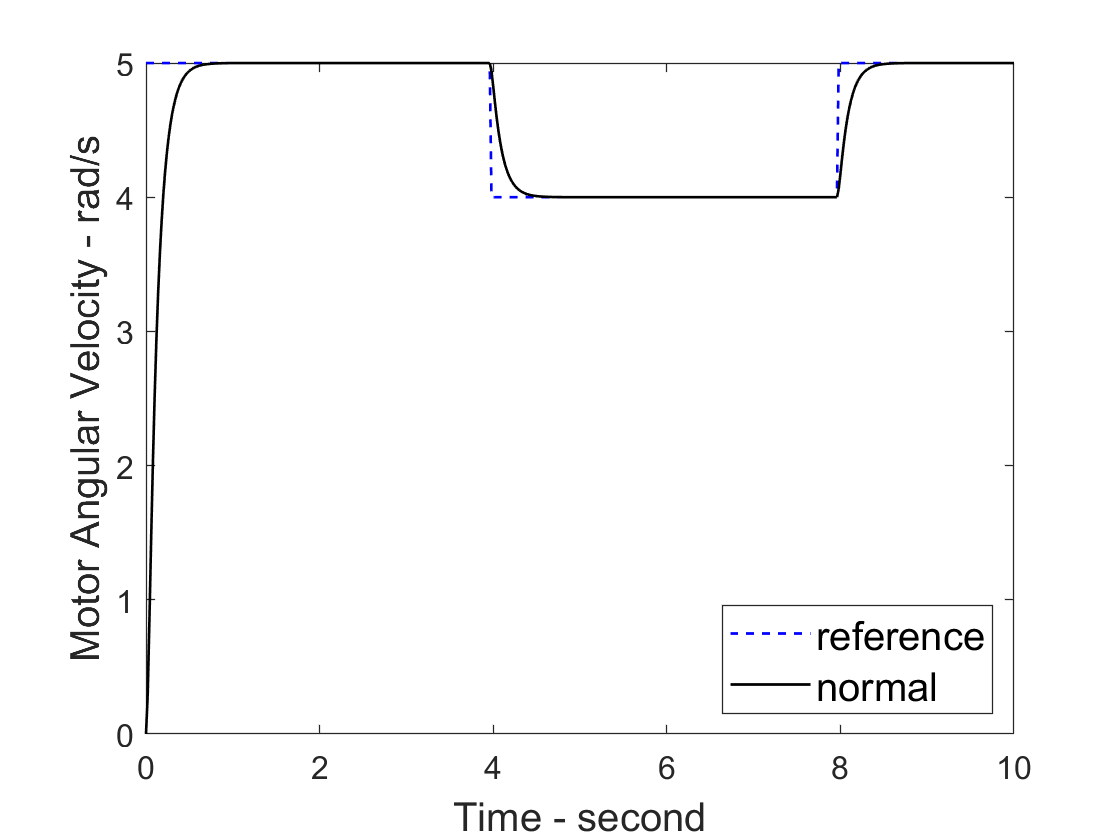

close all

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
y = C * x0;

for i = 2:(t_total/dt+1)
    error = ref(i,1) - y(end,1);
    pid_update(error, dt);
    [y,t,xtemp] = lsim(sys,control*ones(size(0:dt:dt))',(0:dt:dt),xlast);
%     xr = zeros(1, size(x0,2));
%     xr(1:1) = ref(i,1);
%     control = u(xlast,xr)
%     [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
%     y = C * xtemp(end,:)';
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
end

plot(t_span,ref(:,1),'b--',t_span,x(:,1),'k', 'LineWidth', 1);
set(gca,'FontSize',12)
ylabel('Motor Angular Velocity - rad/s','FontSize',15);
xlabel('Time - second','FontSize',15);
legend('reference','normal','Location','SouthEast','FontSize',15);

# Simulation - Attack, No recovery

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

t_attack = 5;

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
% # of measurements
y = zeros(size(t_span,2),1);  
y(1,:) = C * x0;
y_dirty = zeros(size(t_span,2),1);  
y_dirty(1,:) = C * x0;

attack_type = "alter";

% flag
attacked = 0;
last_normal = 0;

for i = 2:(t_total/dt+1)
    if i > t_attack/dt
        if ~attacked
            last_normal = y(i-1,1);
            attacked = 1;
        end
        if strcmp(attack_type,'delay')
%             y_dirty(i-1,1) = last_normal;
            delay_step = 50;
            y_dirty(i-1,1) = y(i-delay_step,1);
        elseif strcmp(attack_type,'alter')
            %y_dirty(i-1,1) = last_normal + 0.001*(i-t_attack/dt)
            y_dirty(i-1,1) = y(i-1,1) - 5;
        elseif strcmp(attack_type,'replay')
            y_dirty(i-1,1) = y(0+(i-t_attack/dt));
        end
    end
    
    error_dirty = ref(i,1) - y_dirty(i-1,1);
    pid_update(error_dirty, dt);
    
    [ytemp,t,xtemp] = lsim(sys,control*ones(size(0:dt:dt))',(0:dt:dt),xlast);
%     [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
%     ytemp = C * xtemp(end,:)';
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    y(i,:) = ytemp(end,:);
    y_dirty(i,:) = ytemp(end,:);
    
end

y

y =          0
    0.2966
    0.8671
    1.4756
    2.0368
    2.5257
    2.9410
    3.2895
    3.5803
    3.8221


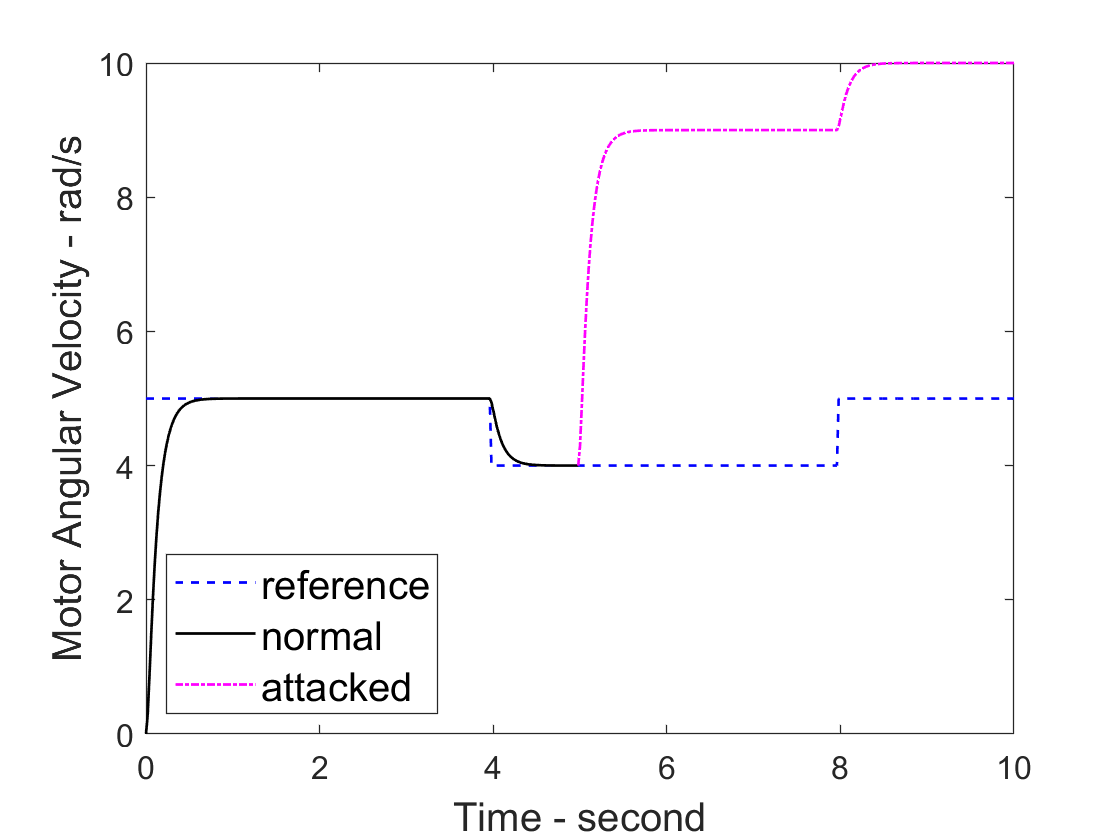


pa = t_attack/dt;
plot(t_span,ref(:,1),'b--',t_span(1,1:pa),x(1:pa,1),'k', ...
    t_span(1,pa:end),x(pa:end,1),'m-.', 'LineWidth', 1);
set(gca,'FontSize',12)
ylabel('Motor Angular Velocity - rad/s','FontSize',15);
xlabel('Time - second','FontSize',15);
legend('reference','normal','attacked','Location','SouthWest','FontSize',15);

# Simulation - Attack, With recovery

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

t_attack = 5;
t_detected = 7;
% recovery steps
k = 15;
inputs = zeros(k,1);

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
% # of measurements
y = zeros(size(t_span,2),1);  
y(1,:) = C * x0;
y_dirty = zeros(size(t_span,2),1);  
y_dirty(1,:) = C * x0;


attack_type = "replay";

% flag
attacked = 0;
last_normal = 0;
detected = 0;
reset = 0;

for i = 2:(t_total/dt+1)
    % detection here
    if i == (t_detected)/dt
        detected = 1;
    end
    % end of detection 
        
    if i > t_attack/dt
        if detected
            % recovery here
            if ~reset
                reset = 1;
                disp('recoverd!');
                [Ad, Bd] = LTI_translation(A,B,dt);
                initial_set_lo = xlast;
                initial_set_up = xlast
                errorbound = [0.3; 100; 100];
                target_set_lo = [ref(i,1);0;0] - errorbound
                target_set_up = [ref(i,1);0;0] + errorbound
                %tic
                utemp = recovery_control(Ad, Bd, k, initial_set_lo, initial_set_up, target_set_lo, target_set_up);
                %timeElapsed = toc
                inputs = utemp((length(utemp)-k+1):end,1);
            end
            % end of recovery  
        else
            if ~attacked
                last_normal = y(i-1,1);
                attacked = 1;
            end
            if strcmp(attack_type,'delay')
                %             y_dirty(i-1,1) = last_normal;
                delay_step = 50;
                y_dirty(i-1,1) = y(i-delay_step,1);
            elseif strcmp(attack_type,'alter')
                %y_dirty(i-1,1) = last_normal + 0.001*(i-t_attack/dt)
                y_dirty(i-1,1) = y(i-1,1) - 5;
            elseif strcmp(attack_type,'replay')
                y_dirty(i-1,1) = y(0+(i-t_attack/dt));
            end
        end
    end
    
    % PID control
    if i<t_detected/dt || i>=t_detected/dt + k
        error_dirty = ref(i,1) - y_dirty(i-1,1);
        pid_update(error_dirty, dt);
    else
        % recovery input
        index = i-t_detected/dt+1
        control = inputs(index,1)
    end
    
    [ytemp,t,xtemp] = lsim(sys,control(end,1)*ones(size(0:dt:dt))',(0:dt:dt),xlast);
%     [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
%     ytemp = C * xtemp(end,:)';
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    y(i,:) = ytemp(end,:);
    y_dirty(i,:) = ytemp(end,:);

    if i == t_detected/dt + k - 1
        index = i-t_detected/dt+1
        xlast
    end
    
end

recoverd!


initial_set_up =    -5.0663
   -7.1654
   -0.0009


target_set_lo =     3.7000
 -100.0000
 -100.0000


target_set_up =     4.3000
  100.0000
  100.0000


Error using linprog (line 361)
LINPROG stopped because some objective or constraint matrix coefficients are too large in magnitude.

Error in recovery_control (line 126)
result = linprog(f, A, b, Aeq, beq);


pa = t_attack/dt;
pr = (t_detected)/dt;
pt = t_detected/dt + k - 1;



plot(t_span,ref(:,1),'b--', ...
    t_span(1,1:pa),x(1:pa,1),'k', ...
    t_span(1,pa:pr),x(pa:pr,1),'m-.', ...
    t_span(1,pr:pt),x(pr:pt,1),'g', 'LineWidth', 1);
set(gca,'FontSize',12);
ylabel('Motor Angular Velocity - rad/s','FontSize',12);
xlabel('Time - second','FontSize',12);
legend('reference','normal','attacked','recovered','Location','NorthWest','FontSize',10);


function dxdt = dynamics(t, x)

global A;
global B;
global control;

dxdt = A*x + B*control;

end